# `'donutPlot.m' `in MATLAB

`Author: Connor Gallimore`

`Original: 12/26/2023`

`Modified: 11/20/2024`

Let's make some fictitious data representing proportions for different groups / subjects.

data= [0.2445	0.2554	0.3237	0.1762;
       0.1924	0.2255	0.1672	0.4147;
       0.1513	0.2769	0.2749	0.2967;
       0.1402	0.3639	0.2439	0.2518]; 

total= sum(data, 2); 

We can see that the columns correspond to the different components of the whole, whereas the groups / subjects lie along the rows.

## The standard pie chart

Let's plot all 4 sets of proportions from left-to-right on the same plot. The native` 'pie.m' `accepts vector input, requiring 4 calls.

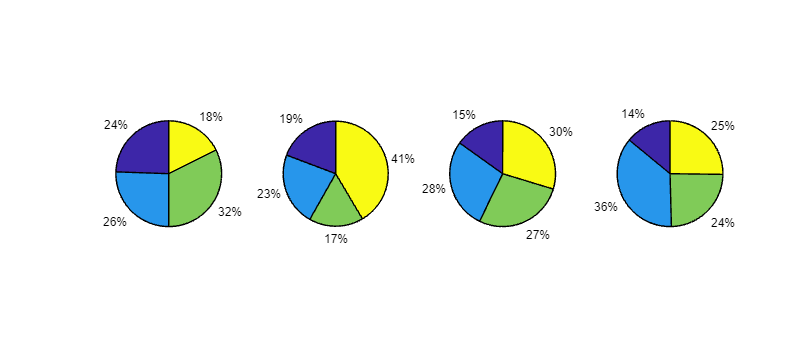

n_subj= size(data, 1); 

wf(1)= figure;  % wide figure
for s= 1:n_subj
    subplot(1, n_subj, s);
    pie(data(s, :));
end

set(wf(1), 'Position', [0 0 900 400]); 

## `'donutPlot.m' `reproduces this using circular arcs instead

However,` 'donutPlot.m' `was designed to handle matrix input by specifying the dimension that individual components of your proportions lie. Here, since each row is a different "group", and each column contains the constituents of the group, we can leave the `'dim'` Name,Value (default `2`) empty.

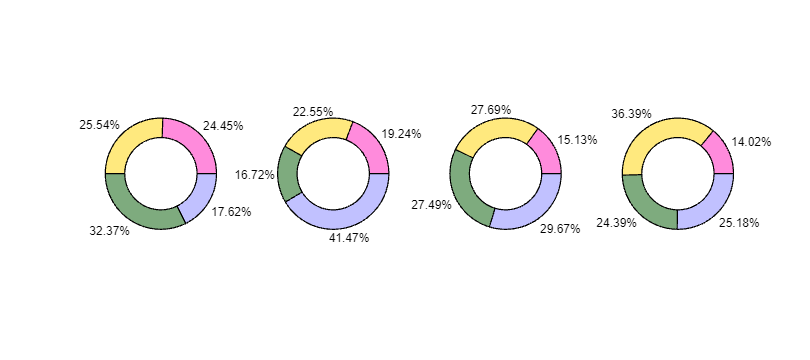

wf(2)= figure;
donutPlot(data);
set(wf(2), 'Position', [0 0 900 400])

For vector input, dimension is optional, and in general dimension is optional, defaulting to` 2 `as above, but can be specified as` 1 `for a transposed input (column = group, rows = components).

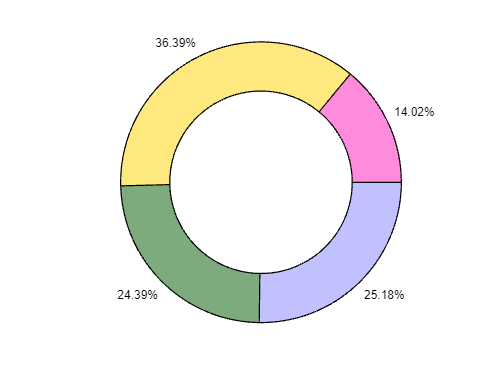

ans = struct with fields:
      axH: [1×1 Axes]
     arcH: [1×1 struct]
     txtH: [1×1 struct]
    color: [4×3 double]


figure; 
donutPlot(data(4, :))

## Storing output as a variable

Notice no semicolon suppression shows a structure of handles to the 1) arcs, 2) text, and 3) colors used in the plot elements is returned, which can be assigned to a variable for later access of these properties. 

wf(3)= figure;
h1= donutPlot(data);
set(wf(3), 'Position', [0 0 900 400])

## Orientation customization

Notice that by default, for matrix input, plotting orientation is horizontal. Though you can indicate vertical plotting using the` 'orientation' `flag as a Name,Value pair.

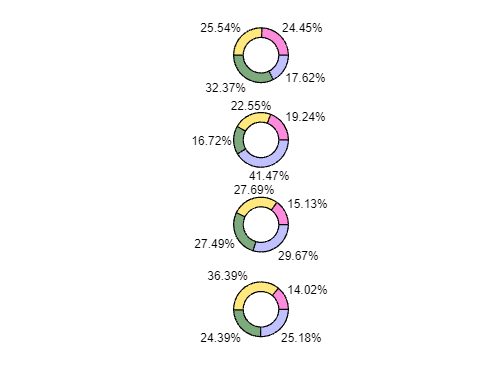

figure;
donutPlot(data, 'orientation', 'vertical');

You can also use a third` 'concentric' `option, which produces concentric circles from inside to outside. Default specification of 

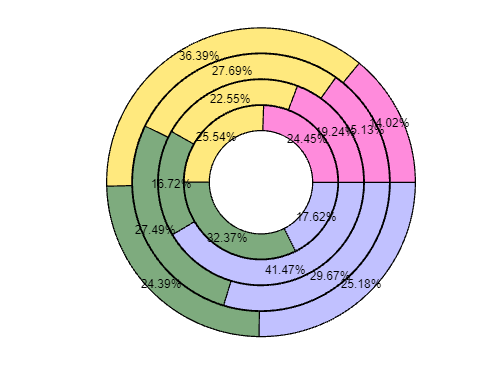

figure;
donutPlot(data, 'orientation', 'concentric');

All of these options support a shorthand specification as well by using `'h'`, `'v'`, or `'c'` for the corresponding above inputs. 

## Altering inner radius & label presence

The` 'innerRadius' `Name,Value pair (case insensitive; as are all following) specifies the inner radius of the donut as a proportion of the outer radius. This means you can plot a simple pie chart with input `0`, and invisible rings with input `1` (default `0.65`). Plot one subject's data and remove text using the `'showLabels'` pair for simplicity. 

Notice here that a second, non- Name,Val pair argument is passed to `donutPlot()` as the target axis, whereas above it was not. This is the recommended usage for combining `donutPlot()` with `subplot()` calls -- especially in loops, which can behave unpredictably. Subplot usage can have some advantages:  for example, individual plots have their own axis, as opposed to one axis containing all plots (default), offering greater control over custom annotations specific to one plot but not the others. For example, the `dp` handle created in the loop below can be used as follows:

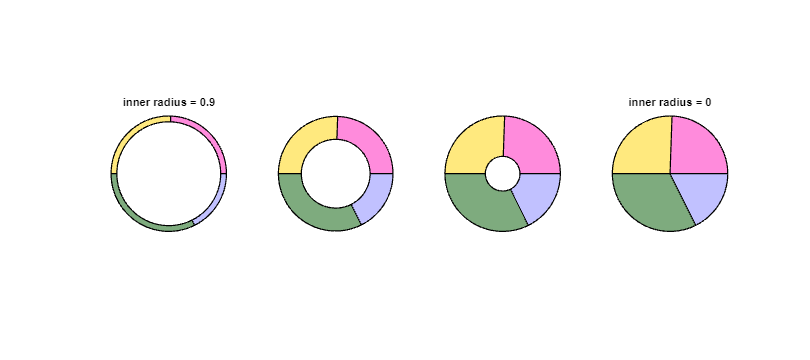

r= 0.9:-0.3:0; 
nr= length(r); 

wf(4)= figure;
for s= 1:nr
    ax(s)= subplot(1, nr, s); hold on; 
    dp(s)= donutPlot(data(1, :), ax(s), 'innerRadius', r(s), 'showLabels', false);
end
set(wf(4), 'Position', [0 0 900 400])


dp(1).axH.Title.String= strcat("inner radius = ", num2str(r(1)));
dp(4).axH.Title.String= strcat("inner radius = ", num2str(r(4)));

NOTE: a loop would be used here regardless, as the function currently only supports a scalar, common radius applied to all groups of matrix input.

## Start angle, direction, & text precision customization

The` 'startAngle' `Name,Value pair allows specification of the angle where all first component patches emanate. Positions correspond to the unit circle, so `0` is 3 o'clock (default), and `90` is midnight. Positive angles step counter-clockwise, whereas negative angles will step clockwise. You can further specify the direction to continue in using `'direction'` and longform or shortform values such as `'clockwise'` / `'cw'` or `'counter-clockwise'` / `'ccw'` (default). Adding the `'precision'` pair here too to specify the max decimal place reported, cleaning up the text a bit. 

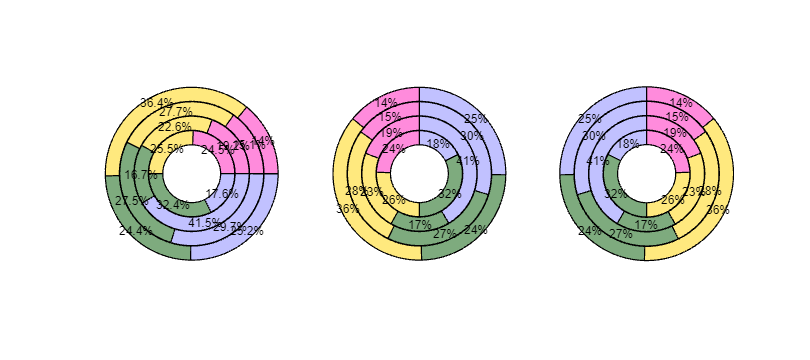

wf(5)= figure;  
sp(1)= subplot(1, 3, 1);
donutPlot(data, sp(1), 'orientation', 'c', 'precision', 1);
sp(2)= subplot(1, 3, 2);
donutPlot(data, sp(2), 'orientation', 'c', 'precision', 0, 'startangle', 90);
sp(3)= subplot(1, 3, 3);
donutPlot(data, sp(3), 'orientation', 'c', 'precision', 0, 'startangle', 90,  'direction', 'cw');
set(wf(5), 'Position', [0 0 900 400])

## Line and color specification

Conforms to the same specs used by default in MATLAB for `'edgeColor'`, `'lineWidth'`, `'textColor'`. I introduce these separately from `'faceColor'` (below) because these 3 receive one argument which is applied to all patch or text elements, whereas `'faceColor'` can receive a 1-to-1 mapping for all patch element faces (i.e. vector or matrix input).

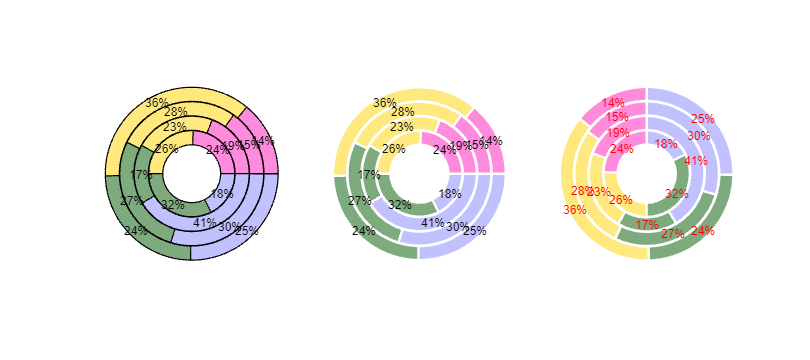

wf(6)= figure;  
subplot(1, 3, 1)
donutPlot(data, 'orientation', 'c', 'precision', 0);
subplot(1, 3, 2)
donutPlot(data, 'orientation', 'c', 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
subplot(1, 3, 3)
donutPlot(data, 'orientation', 'c', 'edgecolor', [1 1 1], 'linewidth', 2, 'textcolor', 'r', 'startangle', 90, 'precision', 0);
set(wf(6), 'Position', [0 0 900 400])

## Facecolor customization

This function utilizes` 'distinguishable_colors.m' `(https://www.mathworks.com/matlabcentral/fileexchange/29702-generate-maximally-perceptually-distinct-colors) to create colors for you, though you are free to pass your own custom color arguments in using` 'facecolor' `followed by an m x 3 array input, where` m == size(data, 1).`

NOTE: cell strings cannot be used for `'FaceVertexCData'`, as written (e.g. changing '`simple_colrs`' to `{'r', 'b', 'c', 'm'}` will error)

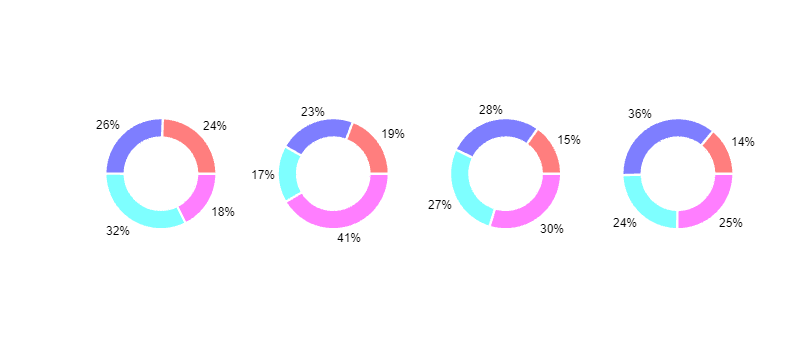

simple_colrs= [1 0 0;
              0 0 1;
              0 1 1;
              1 0 1];
wf(7)= figure;  
donutPlot(data, 'facecolor', simple_colrs, 'precision', 0, 'edgecolor', 'w', 'linewidth', 2);
set(wf(7), 'Position', [0 0 900 400])

## Color scheme

By default, the colors are assigned to the categories (i.e. the various components making up the totals for each group). However, you can alter the color scheme to assign the different colors to each data series, which darkens the custom input (or default) colors for the subsequent components.

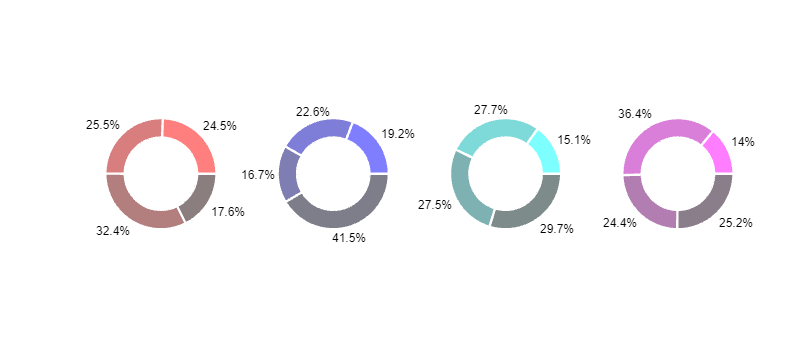

wf(8)= figure;  
donutPlot(data, 'scheme', 'series', 'facecolor', simple_colrs, 'precision', 1, 'edgecolor', 'w', 'linewidth', 2);
set(wf(8), 'Position', [0 0 900 400])

See also the default colors with the series 'scheme'

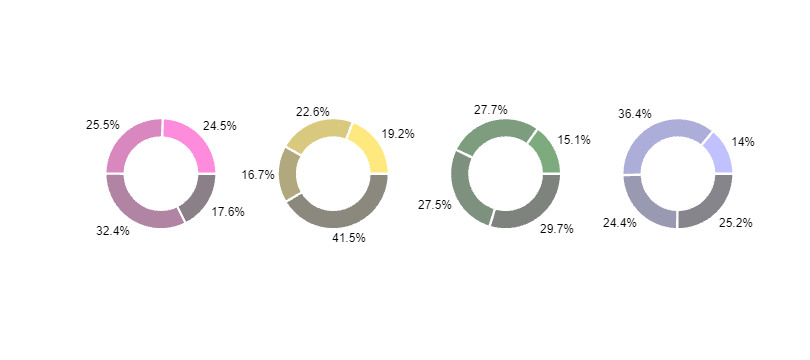

wf(9)= figure;  
donutPlot(data, 'scheme', 'series', 'precision', 1, 'edgecolor', 'w', 'linewidth', 2);
set(wf(9), 'Position', [0 0 900 400])

## Usage with colormaps (MATLAB default or custom)

Since version `2.0.0`, patch colors are controlled with `'FaceVertexCData'`, meaning they can be assigned a value directly for usage with default colormaps

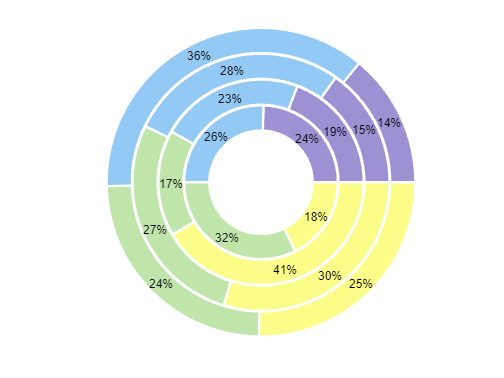

figure;
donutPlot(data, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);

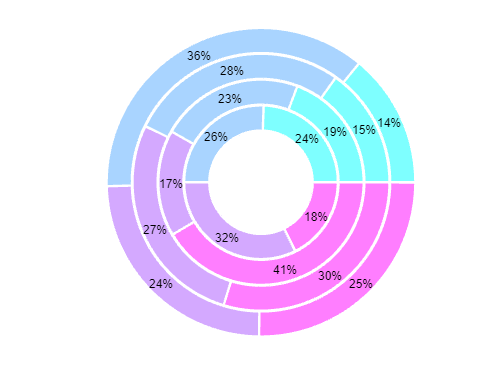

figure;
donutPlot(data, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(cool)

## Multiple colormaps for each plot

Here's just one of many ways you could do this. I did it this way to use 4 different default colormaps, one for each plot.

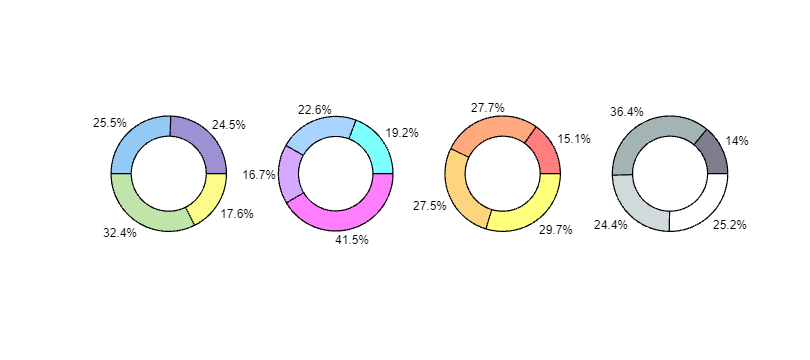

n_comps= size(data, 2);

cmaps= cat(3, parula(n_comps), cool(n_comps), autumn(n_comps), bone(n_comps)); 

wf(10)= figure;  
for s= 1:n_subj
    subplot(1, n_subj, s);
    donutPlot(data(s, :), 'facecolor', cmaps(:, :, s), 'precision', 1);
end
set(wf(10), 'Position', [0 0 900 400])

You can also use this same strategy with` subplot() `to experiment with different grid arrangements

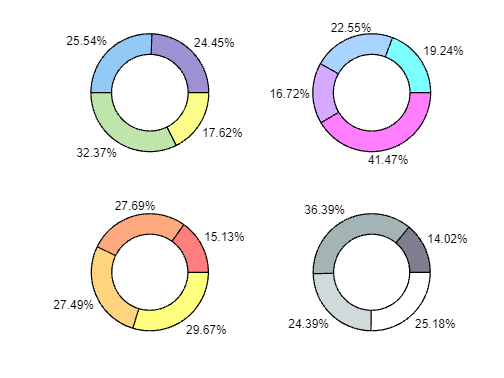

figure;
for s= 1:n_subj
    subplot(2, n_subj/2, s);
    donutPlot(data(s, :), 'facecolor', cmaps(:, :, s));
end

## Recommended usage with legend()

A basic, empty '`legend()`' call will produce an unwieldy display of all patches which redundantly repeat the same colors used across all series.  We can truncate this by editing our legend call to ignore remaining entries (by passing an empty string) and only plot those common to multiple data series. Anyone who's used a legend in MATLAB with '`pie.m`' knows that its default location will likely obscure the data.  We can use the `'Position'` property to achieve a cleaner look

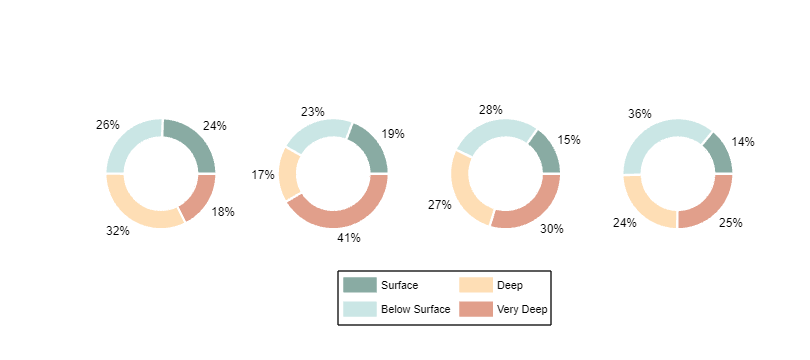

lgd_pad= strings(1, numel(data) - size(data, 2) );   % array of empty strings to pad
lgd_txt= ["Surface", "Below Surface", "Deep", "Very Deep", lgd_pad];

wf(11)= figure;
donutPlot(data, 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(owt)
legend(lgd_txt, "NumColumns", 2, "Position", [0.5 0.1 0.1 0.15])
set(wf(11), 'Position', [0 0 900 400])

Alternatively, see the vertical style:

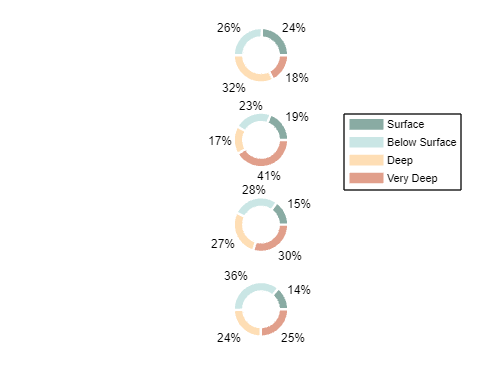

figure;
donutPlot(data, 'orientation', 'v', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(owt)
legend(lgd_txt, "Position", [0.75 0.5 0.1 0.2])

And the concentric style:

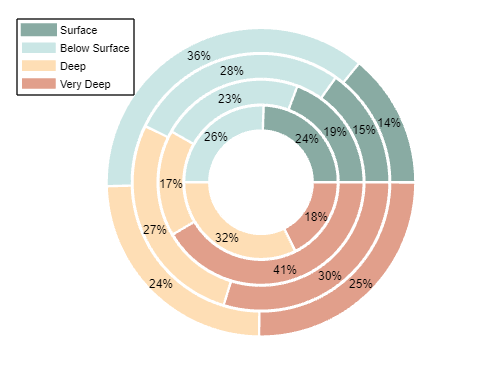

figure;
donutPlot(data, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(owt)
legend(lgd_txt, "Position", [0.1 0.75 0.1 0.2])

You can also use the '`newline`' formalism in versions 2016b and after to 'return' long legend labels:

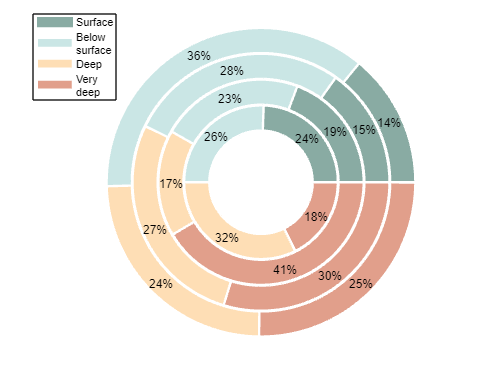

lgd_txt2= [{"Surface", ...
            strcat("Below", string(newline), "surface"), ...
            "Deep", ...
            strcat("Very", string(newline), "deep")}, ...
            lgd_pad];   % dont forget to pad


figure;
donutPlot(data, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(owt)
legend(lgd_txt2, "Position", [0.1 0.75 0.1 0.2])

## Ring separation

Version `2.0.1` introduced `'ringSep'`, specific to the `'concentric'` style, as well as a more unified design which allows this style to obey user defined `'innerRadius'` and `'outerRadius'` arguments. 

`'ringSep'`, like `'innerRadius'`, behaves much like a duty cycle, defining a proportion of the ring's unit radius to instead be a gap between rings. This opens doors for creativity in your plot design. Suppress labels once more for visibility. 

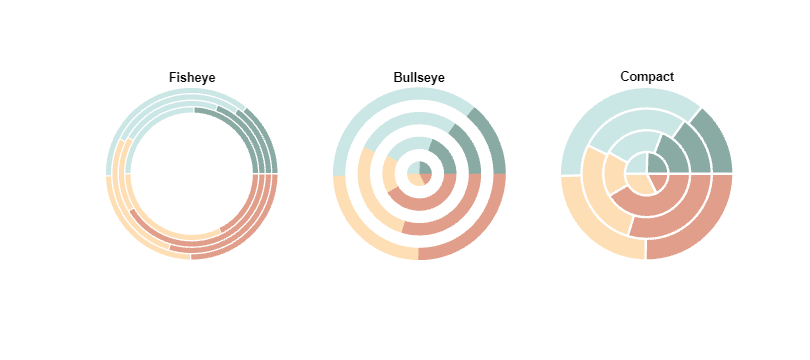

wf(12)= figure;   
subplot(1, 3, 1);
donutPlot(data, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'precision', 0, 'innerradius', 0.7, 'showlabels', false);
colormap(owt);
title('Fisheye');
subplot(1, 3, 2);
donutPlot(data, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'none', 'precision', 0, 'innerradius', 0, 'ringsep', 0.5, 'showlabels', false);
colormap(owt);
title('Bullseye');
subplot(1, 3, 3);
donutPlot(data, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0, 'innerradius', 0, 'ringsep', 0, 'showlabels', false);
colormap(owt);
title('Compact');
set(wf(12), 'Position', [0 0 900 400]);

## Radial legend

Also specific to the `'concentric'` style is a radial legend invoked by `'showLegend'` and its value, a string array of legend labels equal to the number of groups. Take the 'Compact' style from above. 

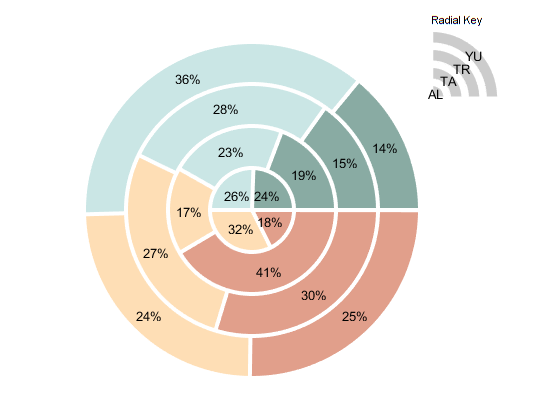

figure;
donutPlot(data, 'orientation', 'c', 'innerradius', 0, 'ringsep', 0, ...
                'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 3, ...
                'precision', 0,  'showlegend', ["AL", "TA", "TR", "YU"]);
colormap(owt);

## Zero handling

Some boring stuff for a bit, `donutPlot()` is capable of handling zeros in one or more of your components. Let's alter our original data matrix to demonstrate this. Notice now that the components in series 1 and 4 dont sum to one. In this case, the function produces a partial arc, as` 'pie.m' `does.

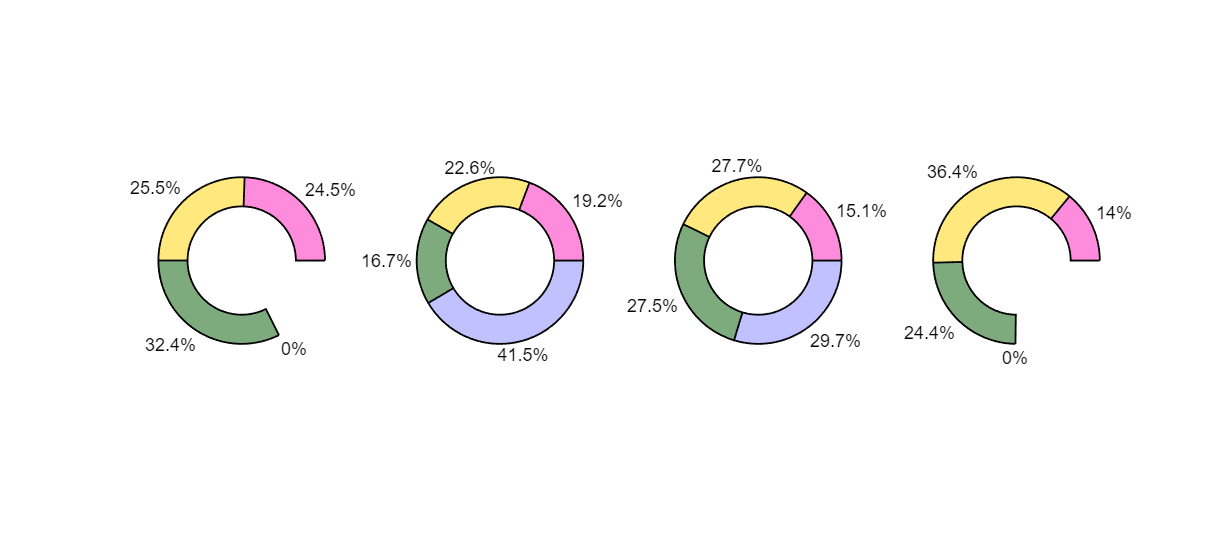

data2= [0.2445	0.2554	0.3237	0;
        0.1924	0.2255	0.1672	0.4147;
        0.1513	0.2769	0.2749	0.2967;
        0.1402	0.3639	0.2439	0]; 

wf(13)= figure;
donutPlot(data2, 'precision', 1);
set(wf(13), 'Position', [0 0 900 400])

## Zero handling II

In the event your data has a 0% component, but the series still sums to 1 (proportions) or 100 (percentages), the function omits this component, as does` 'pie.m'`. In this situation, '`donutPlot()`' invokes a special case which plots the data as a '`polyshape()`' object, producing a complete donut which lacks that pesky, tiny sliver of a '0%' component. Compare the two: 

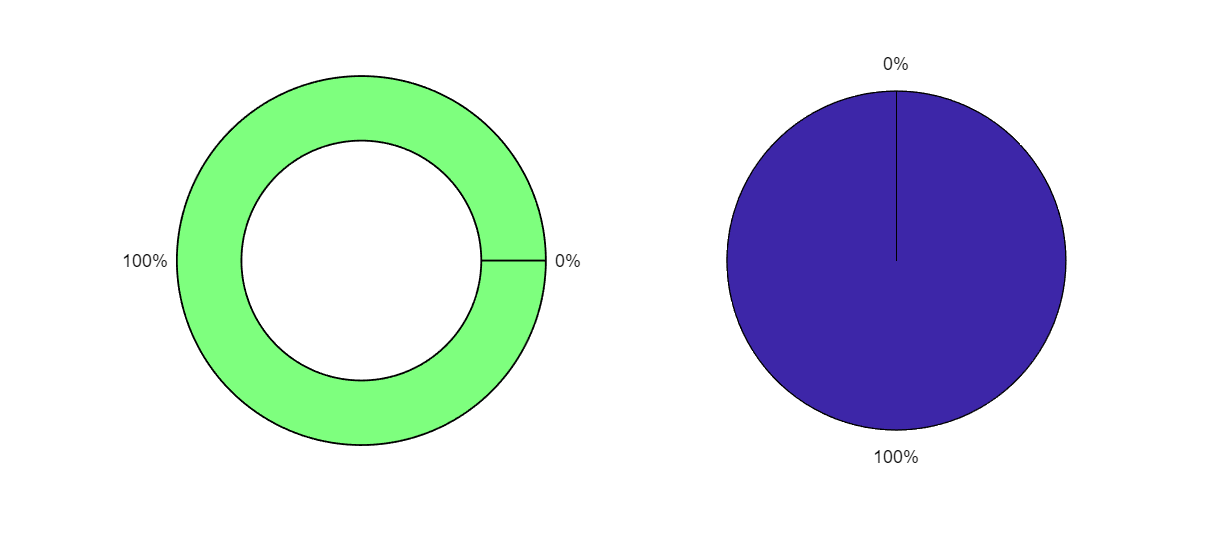

data3= [100 0];
% alternatively, try 
% data3= [34 33 33 0];

wf(14)= figure;
subplot(1, 2, 1);
donutPlot(data3);
subplot(1, 2, 2);
pie(data3);
set(wf(14), 'Position', [0 0 900 400]);

## Zero handling III

The zero doesnt have to be in the last position... Zeroing the second component of series 1 and 4 omits the second category. 

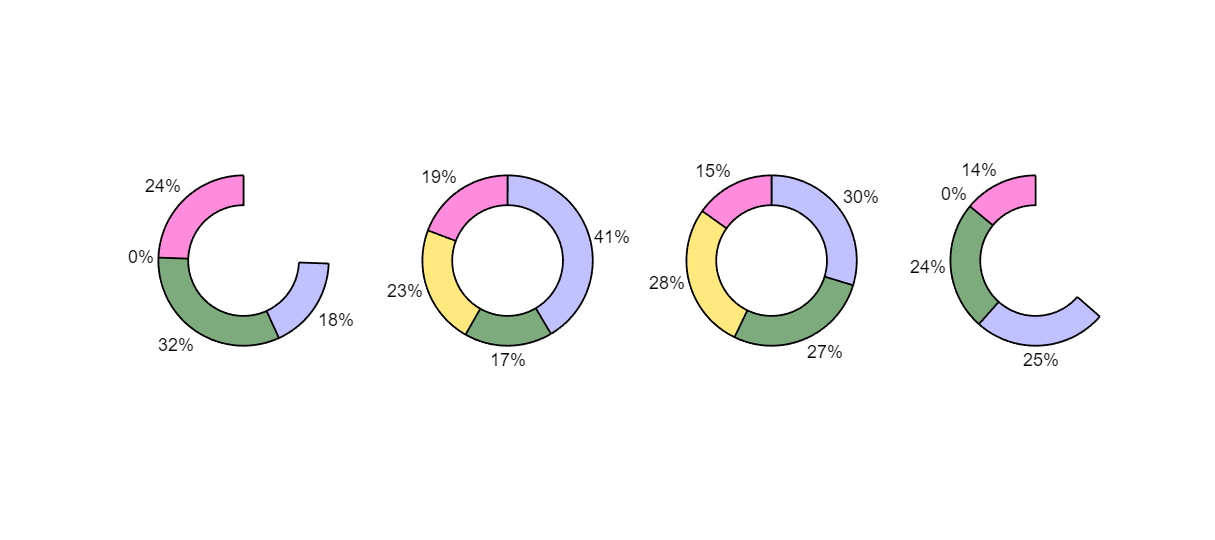

data4= [0.2445	0	0.3237	0.1762;
       0.1924	0.2255	0.1672	0.4147;
       0.1513	0.2769	0.2749	0.2967;
       0.1402	0	0.2439	0.2518]; 

wf(15)= figure;
donutPlot(data4, 'startangle', 90, 'precision', 0); % to mimic pie
set(wf(15), 'Position', [0 0 900 400]);

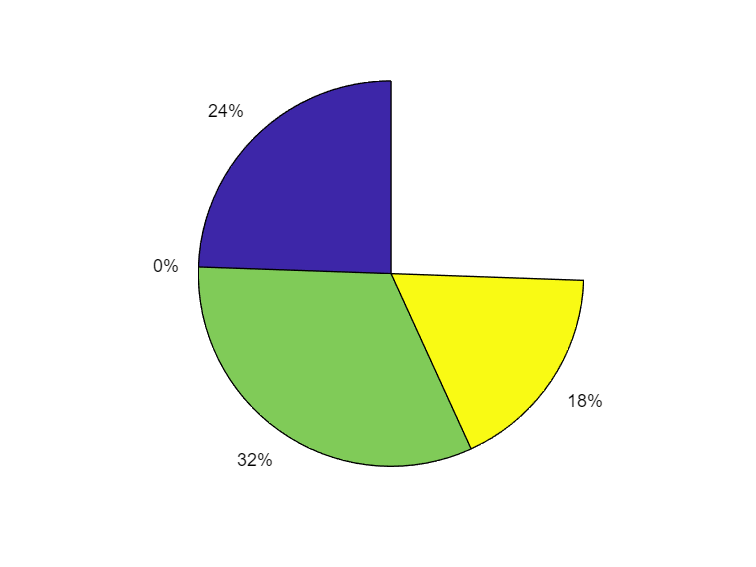


figure; 
pie(data4(1, :))

## Zero handling IV

... or in the same position across consecutive series.

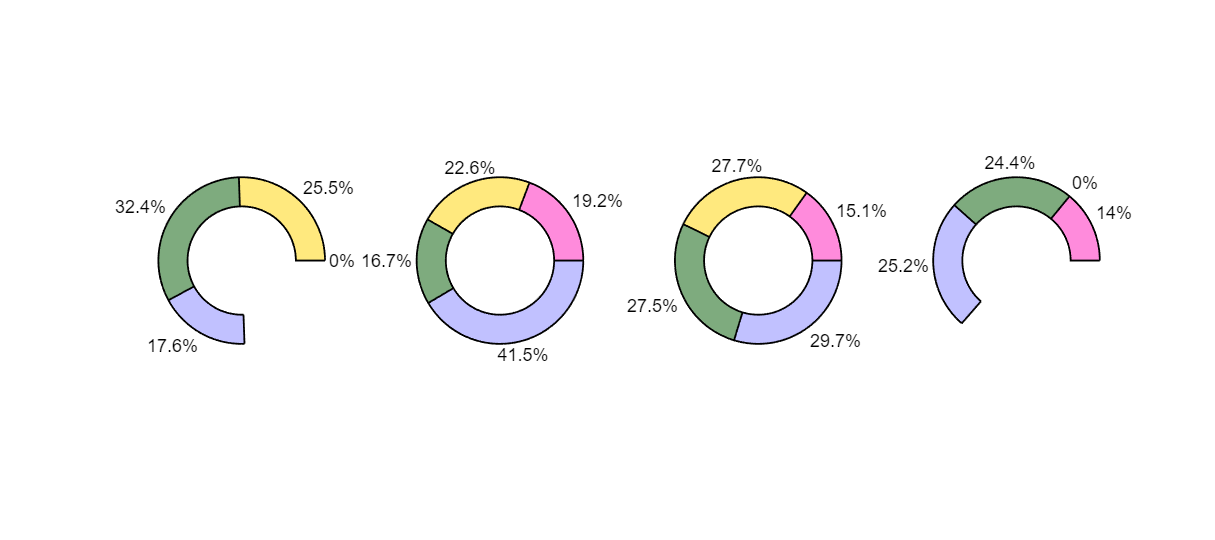

data5= [0	0.2554	0.3237	0.1762;
       0.1924	0.2255	0.1672	0.4147;
       0.1513	0.2769	0.2749	0.2967;
       0.1402	0	0.2439	0.2518]; 

wf(16)= figure;
donutPlot(data5, 'precision', 1);
set(wf(16), 'Position', [0 0 900 400]);

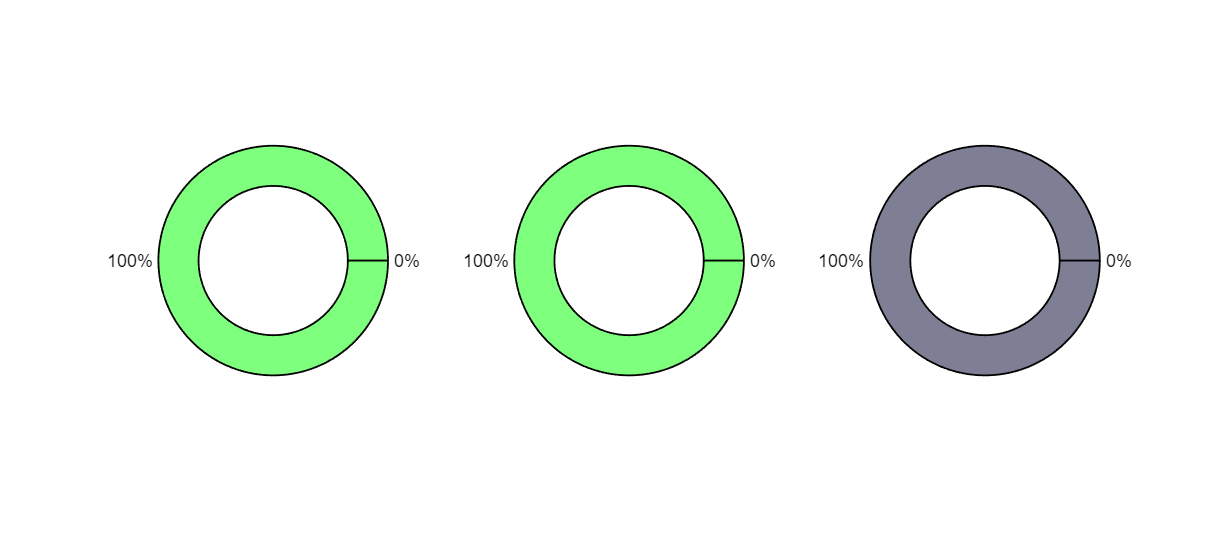


data6= [data3; data3; 0 100];

wf(17)= figure;
donutPlot(data6);
set(wf(17), 'Position', [0 0 900 400]);

## A fully loaded plot call

Note here for both category and group legends, the `legend()` call must specify the main plotting axes, else it will refer to the `uipanel()` axes since they were created most recently inside the function.

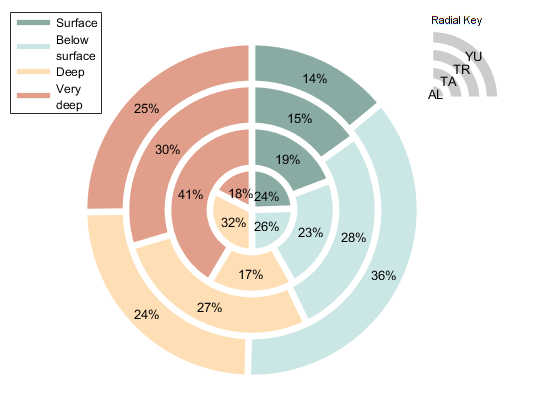

figure; 
dp= donutPlot(data, 'orientation', 'c', 'ringsep', 0, 'innerradius', 0, ...
                    'precision', 0, 'startangle', 90, 'direction', 'cw', ...
                    'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 5, ...
                    'showlegend', ["AL", "TA", "TR", "YU"]);
colormap(owt)
legend(dp.axH, lgd_txt2, "Position", [0.05 0.75 0.1 0.2])

## Local functions

My favorite colormap.

function map = owt(m)

if nargin < 1, m = size(get(gcf,'colormap'), 1); end


values = flipud( [0.7686 0.2588	0.1019;
                  0.9764 0.5607	0.2705;
                  0.9960 0.7490	0.4313;
                     1      1      1;
                  0.5921 0.8078	0.8000;
                  0.0705 0.5647	0.5568;
                  0.0862 0.3490	0.2901] );

P = size(values, 1);
map = interp1(1:P, values, linspace(1, P, m), 'linear');
end